T = [1 1 1; -1 -1 1; 1 -1 -1]';
net = newhop(T);


% generate a grid of starting points from x,y,z (-1,1)
delta=0.5;
i_x = -1:delta:1;
i_y = -1:delta:1;
i_z = -1:delta:1;

n = size(i_x);
m = size(i_y);
l = size(i_z);

% initalize the arrays for recording 
start_record = zeros(3, n(2)*m(2)*l(2));
finish_record = zeros(3, n(2)*m(2)*l(2));
count_record = zeros(1, n(2)*m(2)*l(2));

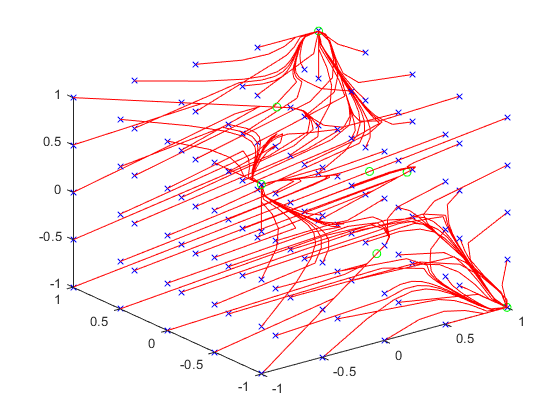

figure 
for i = 1:n(2)
    
    for j = 1:m(2)

       for k = 1:l(2)
           
           index = (i-1)*m(2)*l(2)+(j-1)*l(2)+k;
           a = {[i_x(i);i_y(j);i_y(k)]};
           [y,Pf,Af] = sim(net,{1 100},{},a);   % simulation of the network for 50 timesteps              
           record=[cell2mat(a) cell2mat(y)];   % formatting results  
           start=cell2mat(a);                  % formatting results 
           finish=cell2mat(y(:,end));
           
           count=num2Attractor3D(record);
           
           start_record(:,index)=start;
           
           finish_record(:,index)=finish; 
           
           count_record(index)=count;
           
           plot3(start(1,1),start(2,1),start(3,1),'bx',record(1,:),record(2,:),record(3,:),'r');  % plot evolution
           hold on;
           plot3(record(1,50),record(2,50),record(3,50),'gO');  % plot the final point with a green circle
           
       end
    end  
end

new_start_record = start_record';
new_finish_record = finish_record';
new_count_record = count_record';